%%%% Get data from animal tracks using dung track
% Uses stimulus centre and point opposite stimulus centre as markers for the unit circle on arena
% Gets complete track from each set of trials, makes a plot and uses 
%Initial Direction Analysis to visualize the initial directions of
% purpuratus relative to stimuli of different size John Kirwan Sep 2015

% Can 'clear all' beforehand if required

%data_folder = uigetdir('C:\'); addpath(data_folder) ;   %bring in the dataset with UI         
subfolder = '';     % or manually
file_folder = (strcat('C:\Users\seano\Documents\2021\circular_arena_track\tracks',subfolder));
file_folder = (strcat('C:\Users\Gianni\Documents\GitHub\circular_arena_track\tracks',subfolder));

## and the files

video_name = 'GOPR0243'; %4017
animal_track = importdata(strcat(file_folder,'\',video_name,'_point02.txt')); %tracks of animal throughout trial
landmarks    = importdata(strcat(file_folder,'\',video_name,'_point01.txt')); %origin and stimulus demarcation

% add CircStat to path
%addpath('C:/Users/john/Documents/MATLAB/Apps/CircStat/') % don't need this now
%addpath('C:/Users/john/Documents/MATLAB/thunderdome/')

if mod(size(landmarks, 1),2)  ~= 0           % warning if landmarks uneven
    error('odd number of landmarks') 
end

num_trials = size(landmarks, 1)/2 ;

%find each trial and get data
% (i) frame no (ii - v) coords for centre and stimulus (vi) last frame %
% (vii - viii) normalised stimulus centre (ix) theta in rads (anticlock,
% zero=0) (x) rho in pixels 
trial_limits = get_trial_limits(landmarks, animal_track);

divide the animal tracks up by trial using the first landmark

trackz = get_animal_pos(trial_limits,animal_track) ;

tranz_trackz = trackz_transform(trackz,trial_limits) ; % transform coords to origin and stimulus

% check that animal tracks start below 0.25 and increase

get animal track points closest to rho of 0.25 and 0.5 for each trial

circleValues = zeros([size(trial_limits, 1) 4])    ;

i = 1; 
while i <= size(trial_limits, 1) ;

 [~, index] = min(abs(tranz_trackz{i}(:,2) - 0.25))   ;
 circleValues(i,1:2) = tranz_trackz{i}(index, 1:2) ;
 
 [~, index] = min(abs(tranz_trackz{i}(:,2) - 0.5))   ;
 circleValues(i,3:4) = tranz_trackz{i}(index, 1:2) ;
 
 i = i + 1  ;
end

## %% Create cartesian vector from polar inner and outer circle coordinates 


intersect_angle1 = zeros([num_trials 1]) ;
intersect_angle2 = zeros([num_trials 1]) ;
which_intersect  = zeros([num_trials 1]) ;

for i = 1:num_trials
    [inner_x, inner_y] = pol2cart(circleValues(i,1),circleValues(i,2));
    [outer_x, outer_y] = pol2cart(circleValues(i,3),circleValues(i,4));
    animal_vector(i, 1) = inner_x ;  animal_vector(i, 2) = inner_y ;
    animal_vector(i, 3) = outer_x ;  animal_vector(i, 4) = outer_y ;
    slope(i) = (outer_y - inner_y)/(outer_x - inner_x) ;
    animal_direction(i,1) = outer_x - inner_x;
    animal_direction(i,2) = outer_y - inner_y;
    intercept(i) = animal_direction(i,2) - slope(i) * animal_direction(i,1); %%% JS: This was "- slope(i) * animal_direction(i,2);" but I believe it should be "- slope(i) * animal_direction(i,1);"
    [xout,yout] = linecirc(slope(i),intercept(i),0,0,1) ;
    circle_intersect(i, 1:2) = xout;
    circle_intersect(i, 3:4) = yout; % find x and y points where line intersects with circle

    %get polar coordinates of intersects
    [theta_target1, rho_target1] = cart2pol(circle_intersect(i,1),circle_intersect(i,3))   ;
    [theta_target2, rho_target2] = cart2pol(circle_intersect(i,2),circle_intersect(i,4))   ;
    intersect_angle1(i) = rad2deg(theta_target1) ; 
    intersect_angle2(i) = rad2deg(theta_target2) ;
    % Automatically select intersect closest the outer circle crossing
    dist_to_track(1) = sqrt( (xout(1)-outer_x)^2 + (yout(1)-outer_y)^2 );
    dist_to_track(2) = sqrt( (xout(2)-outer_x)^2 + (yout(2)-outer_y)^2 );
    [~, which_intersect(i)] = min(dist_to_track);
end

%get angle for animal in each trial in degrees and put it in animal_angle
animal_radian = zeros([num_trials 1]) ;
correct_intersect = zeros([num_trials 2]) ;
animal_angle = zeros([num_trials 1]) ;

for i = 1:num_trials
    if     which_intersect(i) == 1
        correct_intersect(i,1) = circle_intersect(i,1);
        correct_intersect(i,2) = circle_intersect(i,3);
    elseif which_intersect(i) == 2
        correct_intersect(i,1) = circle_intersect(i,2);
        correct_intersect(i,2) = circle_intersect(i,4);
    else
        error('Error, must be 1 or 2');
    end
    
    %add animals angle relative to stimulus centre to animal_angle
    animal_radian(i) = cart2pol(correct_intersect(i,1),correct_intersect(i,2));
    animal_angle(i) = rad2deg(cart2pol(correct_intersect(i,1),correct_intersect(i,2)));
    
end

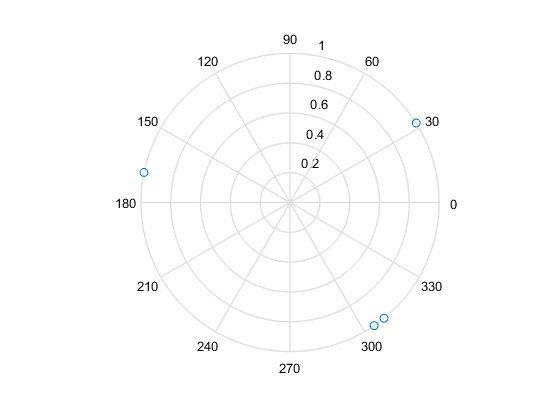

%get the intersect of the tracks with the arena edge
%get_track_intersect(landmarks,animal_track) 
%apply basic circular statistics to trials (uses radians)
% 
% trials_angle_mean = zeros([3 1]);
% [mu ul ll] = circ_mean(animal_radian, [], 2) ;
figure;
circ_labels = num2str(1:length(animal_radian));
directions = circ_plot(animal_radian);

%tracks = circ_plot();

%create csv output with trial number, position and direction in columns
animal_radian_col(:,1) = animal_radian' ;

Unable to perform assignment because the size of the left side is 8-by-1 and the size of the right side is 1-by-4.

animal_radian_col(:,2) = rad2deg(animal_radian') ;

C = {video_name, animal_radian_col(:,1), animal_radian_col(:,2)} ;
S = [video_name,'_directions.csv'];
csvwrite(S,animal_radian_col)